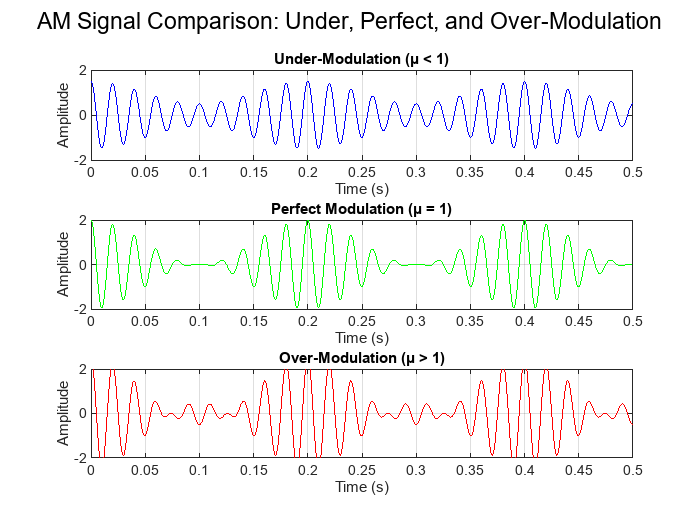


clc; clear; close all;

% Parameters
Ac = 1;                      % Carrier amplitude
Am = [0.5, 1, 1.5];          % Message amplitudes for μ < 1, μ = 1, μ > 1
fc = 50;                     % Carrier frequency (Hz) - reduced for clarity
fm = 5;                      % Message frequency (Hz)
t = 0:0.0005:0.5;            % Extended time vector for better visualization

% Message signal
m = cos(2*pi*fm*t);

% Generate AM signals
s_under = (1 + (Am(1)/Ac)*m) .* cos(2*pi*fc*t);   % μ < 1
s_perfect = (1 + (Am(2)/Ac)*m) .* cos(2*pi*fc*t); % μ = 1
s_over = (1 + (Am(3)/Ac)*m) .* cos(2*pi*fc*t);    % μ > 1

% Plotting
figure;
subplot(3,1,1);
plot(t, s_under, 'b');
title('Under-Modulation (μ < 1)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
ylim([-2 2]);

subplot(3,1,2);
plot(t, s_perfect, 'g');
title('Perfect Modulation (μ = 1)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
ylim([-2 2]);

subplot(3,1,3);
plot(t, s_over, 'r');
title('Over-Modulation (μ > 1)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
ylim([-2 2]);

sgtitle('AM Signal Comparison: Under, Perfect, and Over-Modulation');